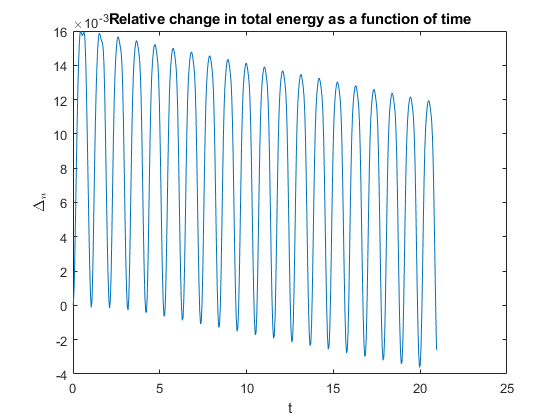

clc
g=9.81;
R=g/9;
theta0=0.25;
thetad0=0;
[t,w]=pendulum(R,theta0,thetad0);
E0=0.5*R^2*thetad0^2+0.5*9*R^2*(sin(theta0)).^2;
K=0.5*R^2*w(:,2).^2;
V=0.5*9*R^2*(sin(w(:,1))).^2;
for i=1:length(t)
delta_E(i)=(K(i)+V(i)-E0)/E0;
end
plot(t,delta_E)
xlabel('t')
ylabel('$\Delta_n$','interpreter','latex')
title('Relative change in total energy as a function of time')

(a) this relative change in total energy has a periodical varation and it is uniformly small during the circle.

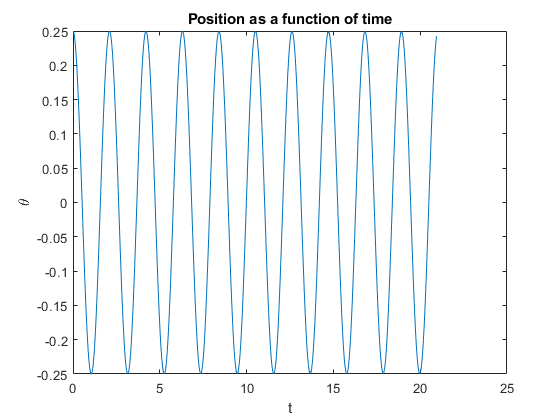

plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time')

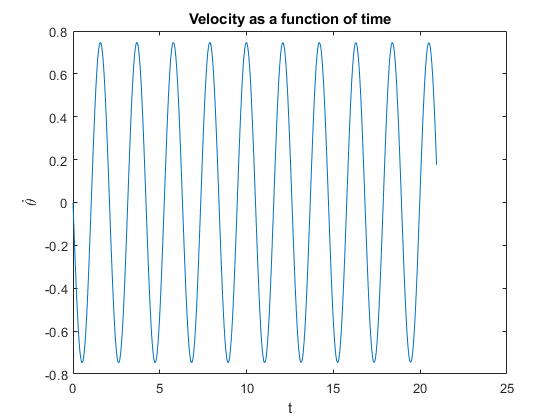

plot(t,w(:,2))
xlabel('t')
ylabel('$\dot{\theta}$','interpreter','latex')
title('Velocity as a function of time')

(b) postion and velocity as a funtion of time 

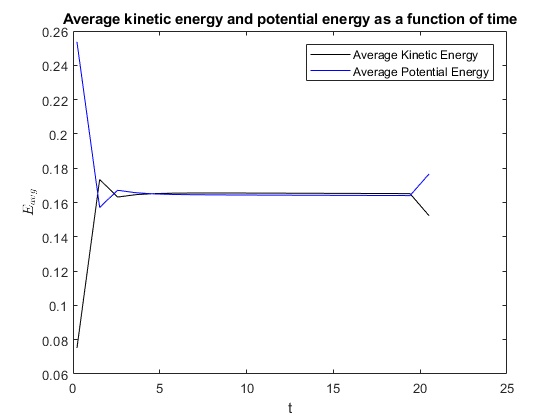

ind= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
for i=1:length(ind)-1
    for j=1:ind(i+1)-ind(i)
        E1(j)=K(ind(i)+j-1);
        V1(j)=V(ind(i)+j-1);
        t1(j)=t(ind(i)+j-1);
    end
    avgK(i)=mean(E1);
    avgV(i)=mean(V1);
    avgt(i)=mean(t1);
    E1=zeros;
    V1=zeros;
    t1=zeros;
end
plot(avgt,avgK,'k-',avgt,avgV,'b-')
legend('Average Kinetic Energy','Average Potential Energy')
xlabel('t')
ylabel('$E_{avg}$','interpreter','latex')
title('Average kinetic energy and potential energy as a function of time')

(c) The sumation of these two averages is  close to a constant. These averages are not continous with time .

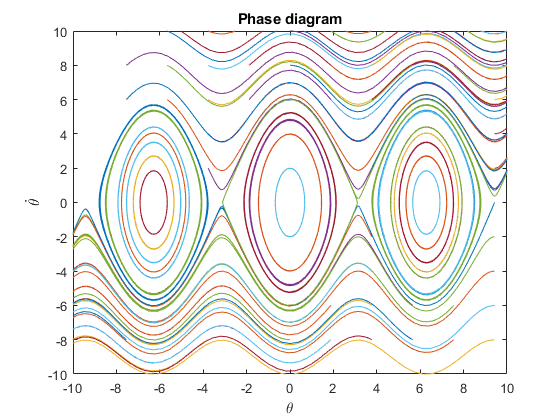

for i=1:10
    for j= 1:10
        theta0=12*j*pi/20-3*pi;
        thetad0=2*i-10;
    [t,w]=pendulum(R,theta0,thetad0);
    plot(w(:,1),w(:,2))
    hold on 
    end
end
axis([-10 10 -10 10])
xlabel('\theta')
ylabel('$\dot{\theta}$','interpreter','latex')
title('Phase diagram')
hold off

(d) They are many paths which correspond to different types of motion. These types are distinguished mainly due to their energy. With small energy (small initial speed), this pendulum with undergo an swinging  (close to SHM). With higher energy, pendulum will rotate instead swinging . The motion will always in the clockwise direction. The reason is that harmonic potential takes the form V= - k*x. With that minus sign, when you have a postive max displacement, the momentum will start to increase in the negative direction after this max-x point. That is to say after (theta_max, 0), you should have (theta_max - delta theta, negative velocity ) . If you connect these two points and put an arrow pointing from (theta_max, 0) to (theta_max - delta theta, negative velocity ), it is in the clockwise direction. 